# Taller OCDR

# Gabriela María Castro Beltrán

## Unconstrained Optimization

### 1.steepest descent method

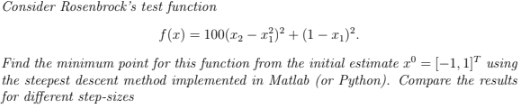

El objetivo principal es aplicar el método de gradiente descendente para minimizar la función de Rosenbrock, una función comúnmente utilizada en problemas de optimización sin restricciones. Esta función es conocida por su valle curvado, lo que la convierte en un desafío interesante para los algoritmos de optimización.

#### El Método del Gradiente Descendente

El método del gradiente descendente es un algoritmo iterativo utilizado para encontrar el mínimo de una función. En cada iteración, se calcula el gradiente de la función en el punto actual y se mueve en la dirección opuesta al gradiente, escalado por una tasa de aprendizaje (α). La regla de actualización está dada por:

#### Desarrollo del Problema

1.  La función de Rosenbrock se definió como una función anónima en MATLAB, permitiendo evaluarla de manera rápida en distintos puntos. Además, el gradiente (las derivadas parciales respecto a x_1 y x_2 se calculó simbólicamente usando `diff`. Esto proporciona la dirección de la pendiente más pronunciada en el espacio de la función.

2. Se inició el algoritmo en el punto (-1, 1), lo que permite explorar el comportamiento del método en un área lejana al mínimo global. También se estableció una tolerancia para detener el algoritmo cuando las magnitudes del gradiente fueran suficientemente pequeñas.

3. Se probaron varios valores de alpha (0.1, 0.001, 0.002, 0.0001) para evaluar cómo afecta la convergencia del método al acercarse al mínimo global.

clc, clearvars, close all

%%% Main Function
f = @(x1,x2)(100*(x2-x1^2)^2+(1-x1)^2)         

f = function_handle with value:
    @(x1,x2)(100*(x2-x1^2)^2+(1-x1)^2)


syms fun x1s x2s
fun=(100*(x2s-x1s^2)^2+(1-x1s)^2)            

$$fun = {\left(\mathrm{x1s}-1\right)}^{2}+100\,{\left(\mathrm{x2s}-{\mathrm{x1s}}^{2}\right)}^{2}$$

#### Gradiente

Df_x = diff(fun,x1s)               

$$Df\_x = 2\,\mathrm{x1s}-400\,\mathrm{x1s}\,\left(\mathrm{x2s}-{\mathrm{x1s}}^{2}\right)-2$$

Df_y = diff(fun,x2s)

$$Df\_y = 200\,\mathrm{x2s}-200\,{\mathrm{x1s}}^{2}$$


grad_x1 = matlabFunction(Df_x)

grad_x1 = function_handle with value:
    @(x1s,x2s)x1s.*2.0-x1s.*(x2s-x1s.^2).*4.0e+2-2.0


grad_x2 = matlabFunction(Df_y)

grad_x2 = function_handle with value:
    @(x1s,x2s)x2s.*2.0e+2-x1s.^2.*2.0e+2


% Condiciones Iniciales
pts(1,1) = -1;                       % x1 posicion
pts(1,2) = 1;                       % x2 posicion
pts(1,3) = f(pts(1,1),pts(1,2));    % z posicion
tolerancia = 1e-10; 
alpha = [0.1, 0.001,0.002,0.0001];                      % learning rate
pts = gradient_descent(grad_x1, grad_x2, f, pts, alpha(1), tolerancia);

Reached target in 50001 iterations
Final pt is (x=NaN,y=NaN,z=NaN)


pts = gradient_descent(grad_x1, grad_x2, f, pts, alpha(2), tolerancia);

Reached target in 50001 iterations
Final pt is (x=1.00,y=1.00,z=0.00)


pts = gradient_descent(grad_x1, grad_x2, f, pts, alpha(3), tolerancia);

Reached target in 50001 iterations
Final pt is (x=1.00,y=1.00,z=0.00)


pts = gradient_descent(grad_x1, grad_x2, f, pts, alpha(4), tolerancia);

Reached target in 50001 iterations
Final pt is (x=0.94,y=0.88,z=0.00)



function pts = gradient_descent(grad_x1, grad_x2, f, pts, alpha, tolerancia)
clc 
for i = 1:50000    
    % Gradiente en el punto actual
    gradx1 = grad_x1(pts(i,1), pts(i,2)); % Evaluar derivada parcial en x1
    gradx2 = grad_x2(pts(i,1), pts(i,2)); % Evaluar derivada parcial en x2

    % Calcula los siguientes x,y,z 
    pts(i+1,1) = pts(i,1) - alpha*gradx1; %x1
    pts(i+1,2) = pts(i,2) - alpha*gradx2; %x2
    pts(i+1,3) = f(pts(i+1,1),pts(i+1,2)); %z (de x1,x2)

    i = i + 1;
    if (abs(gradx1) < tolerancia) && (abs(gradx2) < tolerancia)
    break; % Converge si el gradiente es suficientemente pequeño  
    end
end
% salida
fprintf("Reached target in %d iterations\n",length(pts))
fprintf("Final pt is (x=%1.2f,y=%1.2f,z=%1.2f)\n",pts(end,1),pts(end,2),pts(end,3))
end

#### Visualización

Se generó una visualización 3D de la función de Rosenbrock junto con el camino tomado por el gradiente descendente. Esto permitió observar cómo el método sigue el valle curvado hacia el mínimo global. 

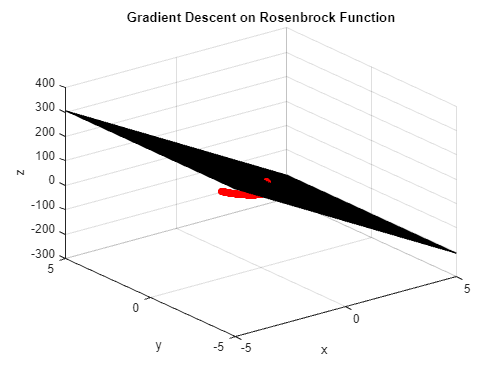


%%%  Visualización
x = -5:.2:5;
y = -5:.2:5;
[X,Y] = meshgrid(x,y);
Z = f(X,Y);
 
surf(X,Y,Z), hold on
xlabel('x'),ylabel('y'),zlabel('z')
title('Gradient Descent on Rosenbrock Function')
% Plot the Path of Points
scatter3(pts(:,1),pts(:,2),pts(:,3),'r','filled')

### Análisis

- α= 0.1**:**Una tasa alta permite avanzar rápidamente, pero puede causar inestabilidad o sobrepasar el mínimo en funciones complejas como la de Rosenbrock. En este caso, se observó que el algoritmo tuvo dificultad para converger debido a oscilaciones.

- α=0.001**:**Este valor más bajo proporcionó un avance más controlado hacia el mínimo, pero requirió muchas iteraciones para lograr la convergencia, lo que aumenta el tiempo de cómputo.

- α=0.002 **:**Representa un compromiso entre rapidez y estabilidad. Se observó que este valor llevó al algoritmo a una convergencia razonablemente rápida sin grandes oscilaciones.

- α=0.0001**:**La tasa de aprendizaje más pequeña ralentizó significativamente el avance. Aunque asegura estabilidad, no es práctico en términos de eficiencia para este problema.

El método de gradiente descendente es una herramienta poderosa para resolver problemas de optimización sin restricciones, pero su eficacia depende en gran medida de la selección de la tasa de aprendizaje. Para funciones como la de Rosenbrock, que presentan valles estrechos y curvados, es crucial encontrar un balance adecuado entre estabilidad y velocidad. α=0.002 se destacó como una buena elección para este caso específico.